Let's assume we have the sysytem of a simplified vehicle dynamics and it's lateral vehicle dynamics as follows: 

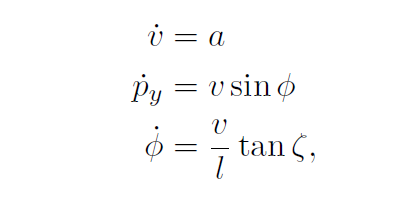


$$\begin{array}{l}
V=\textrm{vehicle}\;\textrm{speed},P_y =\textrm{lateral}\;\textrm{position},\;\phi =\textrm{yaw}\;\textrm{angle}\;\textrm{of}\;\textrm{the}\;\textrm{vehicle}\;\left(\textrm{all}\;\textrm{in}\;\textrm{global}\;\textrm{coordinates}\right)\\
l=\textrm{wheelbase},a=\textrm{acceleration},\;\zeta =\textrm{steering}\;\textrm{angle}
\end{array}$$


Now the control inputs (variables that can change the state of the vehicle) are $u={\left\lbrack a\;\;\zeta \right\rbrack }^T$ , the states are $x={\left\lbrack V\;P_y \;\;\phi \right\rbrack }^T$ and the output is $y=x$

We can see from the equations above that the system is not linear! We have to use the Jacobian matrix to linearize it and calculate it's new A and B matrices!

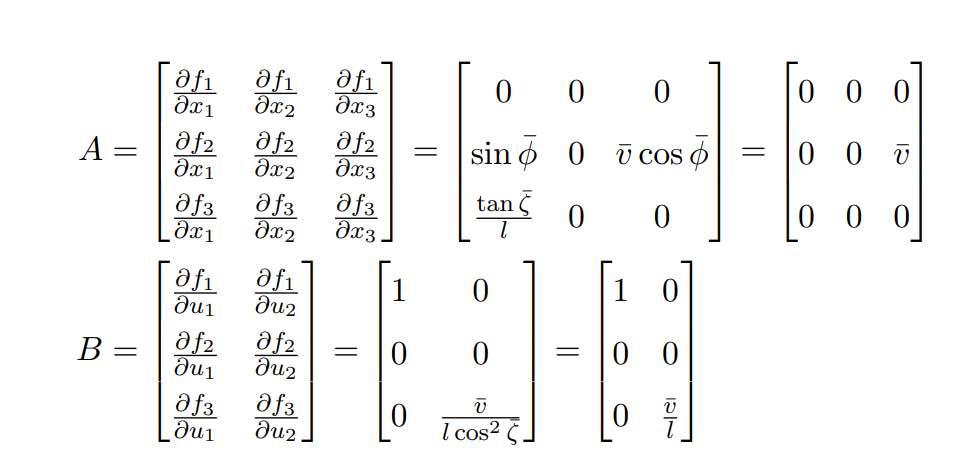

Because the output is the same is the input, we have C as an identity matrix! 

% Define constants
l=3; % the length
xbar = [10; 0; 0]; % the nominal point of the states 10 m/s speed zero letaeral distance and zero heading angle
ubar = [0; 0 ]; % nominal point of the inputs zero steering and acceleration commands
x0 = xbar; % assumming the starting point is the nominal point
Ts = 1; % sampling time, usually it's way less than one
tspan = 0:Ts:5; % we will be simulating for 5 seconds 
u = [0.5; 0.01];
N = numel(tspan); % calculatning the number of elements in tspan


## Now we will define the ordinary defferential equation

% Commented because MATLAB wants all functions to be defined at the end 
% function xdot = lvd ( t , x , u , l )
% xdot = zeros ( 3 , 1 ) ;
% xdot (1) = u ( 1 ) ;
% xdot (2) = x (1)* sin ( x ( 3 ) ) ;
% xdot (3) = x (1)/ l *tan(u ( 2 ) ) ;
% end

now lets run the ODE and store it's states to plot 

[ tn , xn ] = ode45(@( t , x ) lvd ( x , u , l ) , tspan , x0 ) ;  % getting the states of the non-linear sys assuming fixed u =[0.5;0.01]

Now to get the output of the linearized system we shall use the linearized A and  B matrices to compute the output of the system

A = [ 0 0 0;0 0 xbar(1) ; 0 0 0 ] ;
B = [ 1 0;0 0;0 xbar(1)/ l ] ;
C = eye(3);
lsys = ss(A, B, C,0); % linear system with D=0
input = repmat(u,1,N); % create a matrix of inputs so that we have an input at each time step. the 1 means use the u dimensions
[ yl , tl , xl ] = lsim( lsys, input , tspan, x0 ); % will get the output, time and states 

### Transform the system from CT to DT

Ad = A*Ts+eye(3) % Euler discretization

Ad =      1     0     0
     0     1    10
     0     0     1


Bd = B*Ts % Euler discretization

Bd =     1.0000         0
         0         0
         0    3.3333


Let's simulate the output of the DT sys

% dsys = ss(Ad, Bd,C,0)
% [ yd , td , xd ] = lsim( dsys, input , tspan, x0 ); % not exactly sure why
% this gives off results 

td = tl ; xd = zeros ( size ( xl ) ) ;
for n = 2 :N
xd (n , : ) = (Ad*xd (n-1 ,:)' +Bd*u )' ;
end
xd = xd + repmat( x0' ,N, 1 ) ;

## Plot results

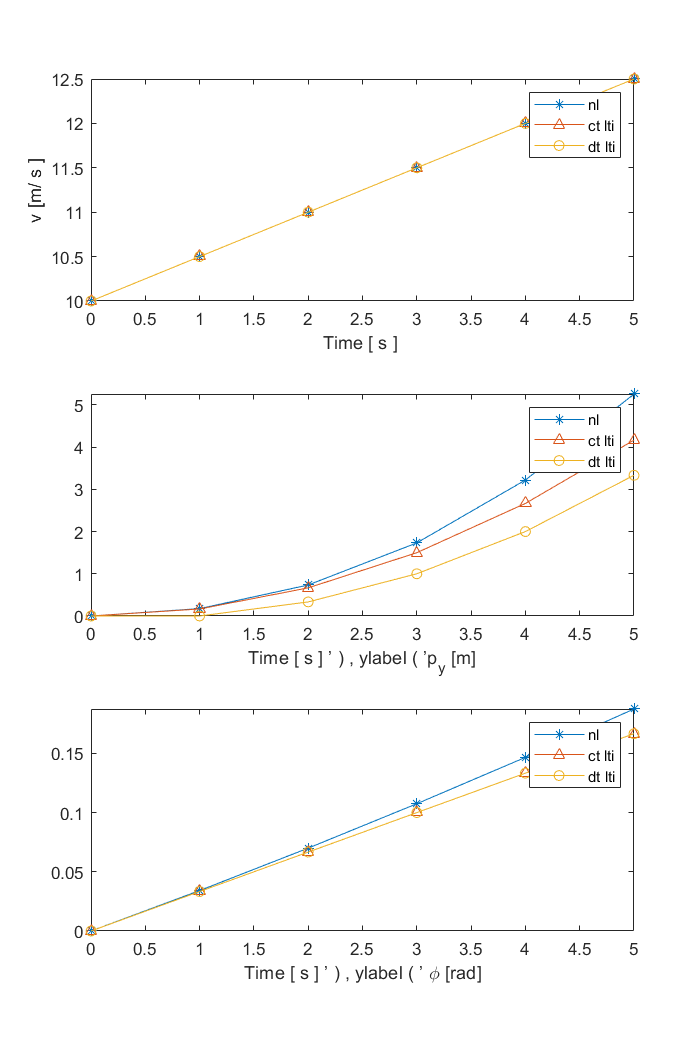

f=figure ;
pos = get ( f , 'Position' ) ; pos(2)= pos(2)/10 ; pos(4) = pos(4)*2 ;
f.Position = pos ;
subplot ( 3 , 1 , 1 ) , plot( tn , xn ( : , 1 ) , '*-' , tl , xl ( : , 1 ) , '^-' , td , xd ( : , 1 ) , 'o-' ) ,
xlabel ( 'Time [ s ] ' ) , ylabel ( 'v [m/ s ]' ) , axis tight ,
legend( 'nl' , 'ct lti' , 'dt lti' )
subplot ( 3 , 1 , 2 ) , plot ( tn , xn ( : , 2 ) , '*-' , tl , xl ( : , 2 ) , '^-' , td , xd ( : , 2 ) , 'o-' ) ,
xlabel ( 'Time [ s ] ’ ) , ylabel ( ’p_y [m]' ) , axis tight ,
legend( 'nl' , 'ct lti' , 'dt lti' )
subplot ( 3 , 1 , 3 ) , plot ( tn , xn ( : , 3 ) , '*-' , tl , xl ( : , 3 ) , '^-' , td , xd ( : , 3 ) , 'o-' ) ,
xlabel ( 'Time [ s ] ’ ) , ylabel ( ’ \phi [rad]' ) , axis tight ,
legend( 'nl', 'ct lti' , 'dt lti' )

## Parameter estimation

Using same system, we would like to generate data using l = 3 (length) and use fmincon function to find the l (length) that produces this results!

% start by setting the starting constants
l = 3 ;
xbar = [ 10 ; 0 ; 0 ] ; x0 = [ 0 ; 0 ; 0 ] ;
Ts = 1 ; u = [ 0.5 ; 0.01 ] ;
t = 0:Ts:5 ; N = numel(t ) ;
A = [ 1 0 0;0 1 xbar(1)*Ts ; 0 0 1 ] ; B = [ Ts 0; 0 0; 0 xbar(1)/l*Ts ] ;
xd = zeros (N, 3 ) ;

% find the states of the system for 6 time steps with intial states [0,0,0]
for n = 2 :N
randomness = randn( 1 , 3 )./[ 10 , 10 , 100 ];
xd (n , : ) = (A*xd(n-1 ,:)' + B*u)' + randomness ;
end
xd = xd + repmat ( x0' ,N, 1 ) ;

% use fmincon to find l using the data we just generated xd;
% l (the control variable) should be between (1,4)
lh = fmincon (@( l ) se( l , xd , xbar , x0 , u , Ts ,N) , 2 , [] , [] , [] , [] , 1 , 4 ) ;


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



% Now we can use the predicted length to plot the states and check how
% close they are 

Ah = [ 1 0 0;0 1 xbar (1)*Ts ; 0 0 1 ] ; Bh = [ Ts 0;0 0;0 xbar(1)/ lh*Ts ] ;
xh = zeros (N, 3 ) ;
for n = 2 :N
xh (n , : ) = (Ah*xh (n-1 ,:)' + Bh*u )' ;
end
xh = xh + repmat ( x0' ,N, 1 ) ;

## Functions

function xdot = lvd (x , u , l )
xdot = zeros ( 3 , 1 ) ;
xdot (1) = u ( 1 ) ;
xdot (2) = x (1)* sin ( x ( 3 ) ) ;
xdot (3) = x (1)/ l *tan(u ( 2 ) ) ;
end

function v = se( l , xd , xbar , x0 , u , Ts ,N)
v = 0 ;
A = [ 1 0 0 ; 0 1 xbar(1)*Ts ; 0 0 1 ] ; B = [ Ts 0 ; 0 0 ; 0 xbar( 1 )/l*Ts ] ;
x = x0 ; % starting with the initail values of the states 
for n = 2 : N
x = A*x+B*u ; % update the values of the states 
v = v + norm( x- xd( n , : )')^2 ; % calculate the error
end
end
